# Zadania laboratorium 4

### Grupa 14:15 A

### Nazwisko i imię: Jakub Mazur 14:15 a

### Zadanie 1

Oblicz oraz sprawdź poprawność wyników.

clear
a=(2^8)/(2^8-1)

a = 1.0039

b=sin(pi)    %niepoprawne, ponieważ pi nie jest "prawdziwym" pi, tylko przybliżonym do pewnej ilości miejsc po przecinku

b = 1.2246e-16

c=cos(pi)

c = -1

d=b+c

d = -1.0000

e=b^2+c^2

e = 1

Przypisz pi wartość 3,14 i oblicz ponownie powyższe równania.

Oblicz błąd względny i bezwzględny.

pi=3.14;
b1=sin(pi)

b1 = 0.0016

b1bb=abs(b-b1)

b1bb = 0.0016

b1bw=b1bb/b

b1bw = 1.3005e+13

c1=cos(pi)

c1 = -1.0000

c1bb=abs(c-c1)

c1bb = 1.2683e-06

c1bw=c1bb/c

c1bw = -1.2683e-06

d1=b1+c1

d1 = -0.9984

d1bb=abs(d-d1)

d1bb = 0.0016

d1bw=d1bb/d

d1bw = -0.0016

e1=b1^2+c1^2

e1 = 1.0000

e1bb=abs(e-e1)

e1bb = 1.1102e-16

e1bw=e1bb/e

e1bw = 1.1102e-16

### Zadanie 2

Utwórz zmienną x=10 i oblicz dla niej podstawowe funkcje matematyczne, przypisują je do zmiennych. Wyświetlaj dane z precyzją do 10 miejsc po przecinku.

- sin(x)

- cos(x)

- tg(x)

- ln(x)

- log(x)

- 

x=10;
digits(10)
z21=vpa(sin(x))

$$z21 = -0.5440211109$$

z22=vpa(cos(x))

$$z22 = -0.8390715291$$

z23=vpa(tan(x))

$$z23 = 0.6483608275$$

z24=vpa(log(x))

$$z24 = 2.302585093$$

z25=vpa(log10(x))

$$z25 = 1.0$$

z26=vpa(x^(1/2))

$$z26 = 3.16227766$$

### Zadanie 3

Utwórz wektor:

- w przedziale [0,10] z krokiem 1,

- w przedziale [-5, 20] z krokiem 0,5,

- w przedziale [-30, 14] z krokiem 3.

Ile elementów ma każdy z wektorów?

w1=0:1:10;
length(w1)

ans = 11

w2=-5:0.5:20;
length(w2)

ans = 51

w3=-30:3:14;
length(w3)

ans = 15

### Zadanie 4

Utwórz wektor:

- w przedziale [0;10] z 10 elementami rozłożonymi równomiernie,

- w przedziale [-15;35] z 150 elementami rozłożonymi równomiernie,

- w przedziale [0;100] z 10 elementami rozłożonymi równomiernie.

Jaka odległość jest pomiędzy poszczególnymi elementami?

w4=linspace(0,10,10);
w4(2)-w4(1)

ans = 1.1111

w5=linspace(-15,35,150);
w5(2)-w5(1)

ans = 0.3356

w6=linspace(0,100,10);
w6(2)-w6(1)

ans = 11.1111

### Zadanie 5

Wygeneruj wektor x w przedziale [0,10] z krokiem 1, i oblicz następujące przykłady:

- y=sin(x)

- y=sin(x)/x

- y=x’*x

- y=x*x’         %’ - macierz transponowana

- y=x.*x

W jaki sposób są obliczane podpunkty c), d), oraz e)?

x=0:1:10;
sin(x)

ans =          0    0.8415    0.9093    0.1411   -0.7568   -0.9589   -0.2794    0.6570    0.9894    0.4121   -0.5440


sin(x)/x

ans = 0.0113

x'*x %mnozymy 1 kolumnę razy 1 wiersz, z mnozenia macierzy dostaniemy tabliczkę mnożenia, (iloś kolumn i wierszy ma rowną ilości wierszy 1 macierzy)

ans =      0     0     0     0     0     0     0     0     0     0     0
     0     1     2     3     4     5     6     7     8     9    10
     0     2     4     6     8    10    12    14    16    18    20
     0     3     6     9    12    15    18    21    24    27    30
     0     4     8    12    16    20    24    28    32    36    40
     0     5    10    15    20    25    30    35    40    45    50
     0     6    12    18    24    30    36    42    48    54    60
     0     7    14    21    28    35    42    49    56    63    70
     0     8    16    24    32    40    48    56    64    72    80
     0     9    18    27    36    45    54    63    72    81    90


x*x' %mnozymy 1 wiersz razy kolumnę, ponieważ 1 macierz ma 1 wiersz dostaniemy macierz 1x1, czyli 1 liczbę

ans = 385

x.*x %jest to mnożenie tablicowe, czyli każdy element na miejscu nm z 1 macierzy * element na miejscu nm z 2 macierzy

ans =      0     1     4     9    16    25    36    49    64    81   100


### Zadanie 6

Utwórz 2 wektory (tego samego rozmiaru) zawierające losowe liczby. Zapisz otrzymane dane, wczytaj je w Excelu oraz utwórz wykres punktowy.

x6=floor(rand*10+5);
we1=rand(1,x6);
we2=rand(1,x6);
xlswrite('temat4exel.xls',we1,1)
xlswrite('temat4exel.xls',we2,2)

### Zadanie 7

Wygeneruj macierz:

- jednostkową o wymiarach 5x5,

- wypełnioną zerami o wymiarach 2x2,

- wypełnioną zerami o wymiarach 3x5,

- wypełnioną jedynkami o wymiarach 7x7,

- wypełnioną jedynkami o wymiarach 4x5,

- wypełnioną losowymi liczbami o wymiarach 3x3.

eye(5)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


zeros(2)

ans =      0     0
     0     0


zeros(3,5)

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


ones(7)

ans =      1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1
     1     1     1     1     1     1     1


ones(4,5)

ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


rand(3)

ans =     0.0300    0.8021    0.9394
    0.5357    0.9891    0.0182
    0.0871    0.0669    0.6838


### Zadanie 8

Utwórz dowolną, kwadratową macierz A o rozmiarze 5.

Dla danej macierzy:

- oblicz wyznacznik,

- oblicz macierz odwrotną,

- transponuj macierz A,

- wyznacz maksymalne elementy dla kolumn oraz wierszy,

- wyznacz średnie wartości kolumn oraz wierszy.

A=rand(5)*10

A =     7.8374    1.3787    6.1644    9.4558    6.6238
    5.3414    2.1780    9.3966    6.7664    2.4417
    8.8536    1.8214    3.5446    9.8830    2.9551
    8.9900    0.4182    4.1063    7.6683    6.8018
    6.2594    1.0694    9.8435    3.3670    5.2785


inv(A)

ans =    -0.2535   -0.1537    0.2497    0.0389    0.1993
    1.9236   -2.5071    1.7045   -3.1939    1.9073
   -0.3216    0.5004   -0.3109    0.4692   -0.2585
   -0.2036    0.6091   -0.3790    0.5776   -0.5584
    0.6404   -0.6315    0.1802   -0.6425    0.4049


A'

ans =     7.8374    5.3414    8.8536    8.9900    6.2594
    1.3787    2.1780    1.8214    0.4182    1.0694
    6.1644    9.3966    3.5446    4.1063    9.8435
    9.4558    6.7664    9.8830    7.6683    3.3670
    6.6238    2.4417    2.9551    6.8018    5.2785


max(A)

ans =     8.9900    2.1780    9.8435    9.8830    6.8018


sA=size(A);
sum(A)/sA(1)

ans =     7.4564    1.3731    6.6111    7.4281    4.8202


### Zadanie 9

Utwórz dowolne macierze A oraz B.

Oblicz AB oraz BA tablicowo oraz macierzowo.

t=floor(rand*10);
A=rand(t)*10;
B=rand(t)*10;
A.*B

ans =     7.5724   40.4874   76.7991   64.6745
   23.1847    0.5017    1.5124   10.1978
   42.3706    6.9643   36.7317   11.1235
   43.1983   66.3683   24.4018   14.6540


B.*A

ans =     7.5724   40.4874   76.7991   64.6745
   23.1847    0.5017    1.5124   10.1978
   42.3706    6.9643   36.7317   11.1235
   43.1983   66.3683   24.4018   14.6540


A*B

ans =   167.3362  208.1483  149.0662  143.5206
   86.5812  124.4046  105.4790  106.3717
  112.7734  160.5953  111.1911   98.3790
   71.3635   88.2832   74.0483   80.3677


B*A

ans =   144.8843  101.7034  137.2678   90.4432
   34.2168   35.0197   43.0337   34.4792
  143.9573  108.0146  148.2792  124.2063
  194.6396  147.1395  202.4128  155.1164


### Zadanie 10

Dane są macierze A i B 

A=[4 5 7 0; 2 10 12 24; 32 2 3 5]

B=[3 8 7 0;34 3 12 18; 20 5 1 5]

sprawdź podane poniżej relacje i ich skutek:

A<B, A<=B, A>B, A>=B, A==B, A~=B, A|B, A&B, B&A, (A>B)|(B<A), (A>B)&(B<A)

A=[4 5 7 0; 2 10 12 24; 32 2 3 5];
B=[3 8 7 0;34 3 12 18; 20 5 1 5];
A<B

ans = 3×4 logical array
   0   1   0   0
   1   0   0   0
   0   1   0   0


A<=B

ans = 3×4 logical array
   0   1   1   1
   1   0   1   0
   0   1   0   1


A>B

ans = 3×4 logical array
   1   0   0   0
   0   1   0   1
   1   0   1   0


A>=B

ans = 3×4 logical array
   1   0   1   1
   0   1   1   1
   1   0   1   1


A==B

ans = 3×4 logical array
   0   0   1   1
   0   0   1   0
   0   0   0   1


A~=B

ans = 3×4 logical array
   1   1   0   0
   1   1   0   1
   1   1   1   0


A|B

ans = 3×4 logical array
   1   1   1   0
   1   1   1   1
   1   1   1   1


A&B

ans = 3×4 logical array
   1   1   1   0
   1   1   1   1
   1   1   1   1


B&A

ans = 3×4 logical array
   1   1   1   0
   1   1   1   1
   1   1   1   1


(A>B)|(B<A)

ans = 3×4 logical array
   1   0   0   0
   0   1   0   1
   1   0   1   0


(A>B)&(B<A)

ans = 3×4 logical array
   1   0   0   0
   0   1   0   1
   1   0   1   0


### Zadanie 11

Rozwiąż układy równań:

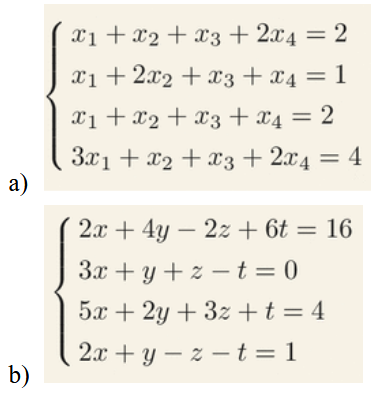

(Oblicz na dwa sposoby: korzystając z funkcji inv oraz dzielenia lewostronnego) 

clear
Aa=[1 1 1 2; 1 2 1 1; 1 1 1 1; 3 1 1 2];
ba=[2;1;2;4];
inv(Aa)*ba

ans =     1.0000
   -1.0000
    2.0000
    0.0000


Aa\ba

ans =      1
    -1
     2
     0


Ab=[2 4 -2 6; 3 1 1 -1; 5 2 3 1; 2 1 -1 -1];
bb=[16; 0; 4; 1];
inv(Ab)*bb

ans =     1.0000
   -0.0000
   -1.0000
    2.0000


Ab\bb

ans =     1.0000
   -0.0000
   -1.0000
    2.0000


### Zadanie 12

Utwórz skrypt liczący pole koła oraz obwód okręgu o zadanym promieniu.

clear
r=9;
pi*r*r

ans = 254.4690

2*pi*r

ans = 56.5487

clear

### Zadanie 13

Utwórz skrypt z zadania 3, tak aby promień był wpisywany przez Użytkownika.

r=input('podaj promien: ')

r = 5

pi*r*r

ans = 78.5398

2*pi*r

ans = 31.4159

### Zadanie 14

Utwórz skrypt wyznaczający n elementów ciągu Fibonacciego (parametr n zadawany jest przez Użytkownika).

clear
n=input("podaj nr ciągu fibonaciego: ")

n = 5

if(n<3)
    1 
else
    i=3;
    w1=1;
    w2=1;
    while(i<=n)
        t=w2;
        w2=w2+w1;
        w1=t;
        i=i+1;
    end
w2
end

w2 = 5

### Zadanie 15a

Wykorzystując 2 pętle for jedna wewnątrz drugiej utwórz macierz A będącą iloczynem numeru kolumny i wiersza. Przyjmij liczbę wierszy i kolumn od 1 do 10. Macierz A powinna przypominać tabliczkę mnożenia o wymiarach 10x10.

T=ones(10);
for i= 1:10
    for j=1:10
        T(i,j)=i*j;
    end
end
T

T =      1     2     3     4     5     6     7     8     9    10
     2     4     6     8    10    12    14    16    18    20
     3     6     9    12    15    18    21    24    27    30
     4     8    12    16    20    24    28    32    36    40
     5    10    15    20    25    30    35    40    45    50
     6    12    18    24    30    36    42    48    54    60
     7    14    21    28    35    42    49    56    63    70
     8    16    24    32    40    48    56    64    72    80
     9    18    27    36    45    54    63    72    81    90
    10    20    30    40    50    60    70    80    90   100


### Zadanie 15b

Mając dany wektor x=[1 15 7 12 -1 0 -15 9 5 2], napisz polecenia wykonujące następujące operacje:

a) podmień dodatnie elementy wektora x na zera

b) pomnożyć parzyste elementy wektora x przez 100

c) utworzyć wektor y złożony z elementów x pomnożonych przez 20

d) wymienić zerowe elementy na liczbę pseudolosową

e) policzyć sumę elementów wektora x wykorzystując pętle. Polecenie sum(x) użyj do sprawdzenia swojego wyniku.

x=[1 15 7 12 -1 0 -15 9 5 2]; xa=x; xb=x; y=x*20; xd=x; sm=0

sm = 0

s=size(x);
for i=1:s(2)
    if(x(i)>0) 
        xa(i)=0;
    end
    if(mod(x(i),2)==0)
        xb(i)=xb(i)*100;
    end
    if(x(i)==0)
        xd(i)=rand;
    end
    sm=sm+x(i);
end
xa

xa =      0     0     0     0    -1     0   -15     0     0     0


xb

xb =            1          15           7        1200          -1           0         -15           9           5         200


y

y =     20   300   140   240   -20     0  -300   180   100    40


xd

xd =     1.0000   15.0000    7.0000   12.0000   -1.0000    0.1822  -15.0000    9.0000    5.0000    2.0000


sm

sm = 35

if(sm==sum(x)) 
    "jest to dobry wynik"
else
    "jest to niepoprawny wynik"
end

ans = "jest to dobry wynik"

### Zadanie 16*

Utwórz funkcję objętość(x,y,z) liczącą objętość prostopadłościanu o podanych wielkościach.

function v = objetosc(x,y,z)
    v=x*y*z;
end

### Zadanie 17*

Utwórz funkcję odległość, wyznaczającą odległość pomiędzy dwoma punktami P1 oraz P2.

function d=odleglosc(P1,P2)
    d=((P2(1)-P1(1))^2+(P2(2)-P1(2))^2)^(1/2);
end

### Zadanie 17a*

Rozbuduj funkcję aby wyznaczała również równanie prostej przechodzącej przez podane punkty.

function l=rownanie(P1,P2)
    A=[P1(1) 1; P2(1) 1];
    b=[P1(2); P2(2)];
    l=inv(A)*b;
end

# Podsumowanie i wnioski

Tu umieść podsumowanie i wnioski